# **META 2**

10. Carregue a estrutura de dados guardada no último ponto da meta anterior.

dados = load("dados.mat").dados;

tabela = struct2table(dados); 
disp(tabela);

          diretorio            nomeFicheiro      participante    digito    repeticao         sinal          taxaAmostragem    taxaCruzamentoZeros    energiaTotal    tAmplitudeMaxima    razaoAmplitude    desvioPadrao    coeficientesFourier    maxEspetraisAmplitudes    maxEspetraisPosicao    mediaAmplitudesFrequencias     SEF  
    ______________________    _______________    ____________    ______    _________    ________________    ______________    ___________________    ____________    ________________    ______________

11. Para cada sinal obtido após o pré-processamento, determine os coeficientes da série complexa de Fourier e guarde na estrutura de dados do ponto anterior.

for i = 1:length(dados)
    sinal = dados(i).sinal;
    tamanhoSinal = length(sinal);
    
    % Zero-padding na FFT para melhor resolução de frequência
    tamanhoPadding = 2^nextpow2(tamanhoSinal); 

    % Calculo da transformada com padding e normalização 
    %coeficientesFourier = fft(sinal, tamanhoPadding) / tamanhoSinal;
    
    % Calculo sem padding e normalização
    coeficientesFourier = fft(sinal) / tamanhoSinal;

    dados(i).coeficientesFourier = coeficientesFourier;
end


12. Calcule para cada dígito, o espectro de amplitude mediano, normalizado pelo número de amostras (i.e., equivalente ao módulo dos coeficientes da série complexa de Fourier), e somente para frequências positivas. Calcule também o primeiro quartil (25%) e terceiro quartil (75%). A Figura 4 mostra um exemplo. Compare os gráficos obtidos.

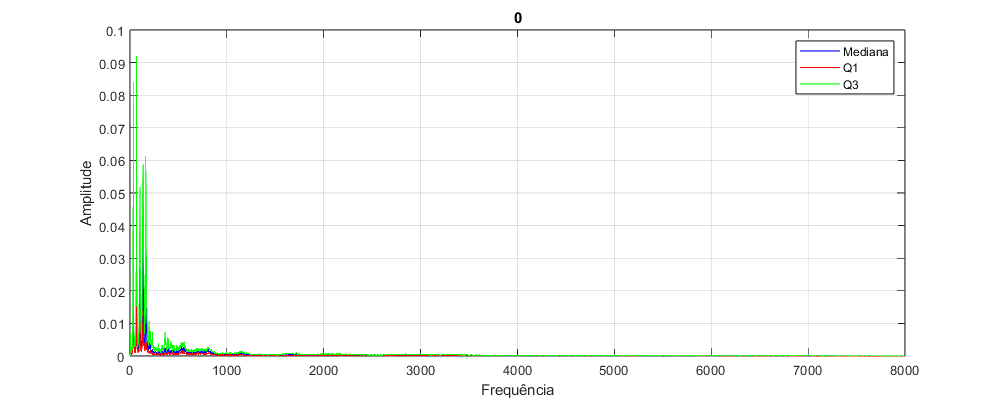

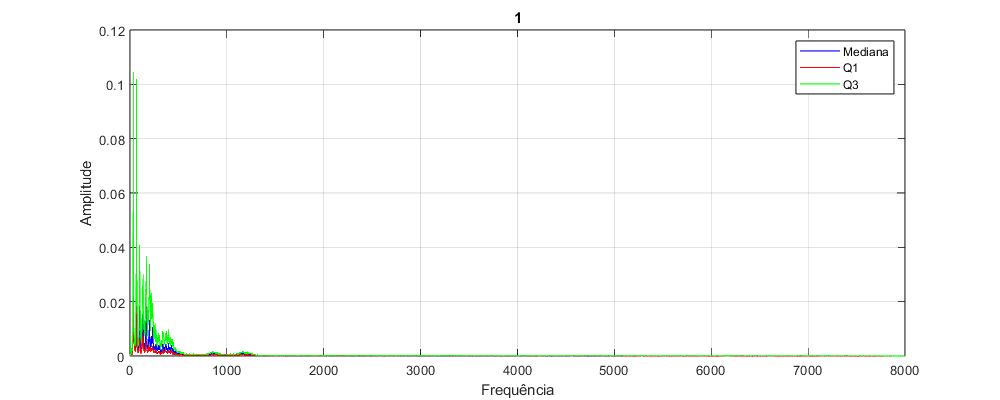

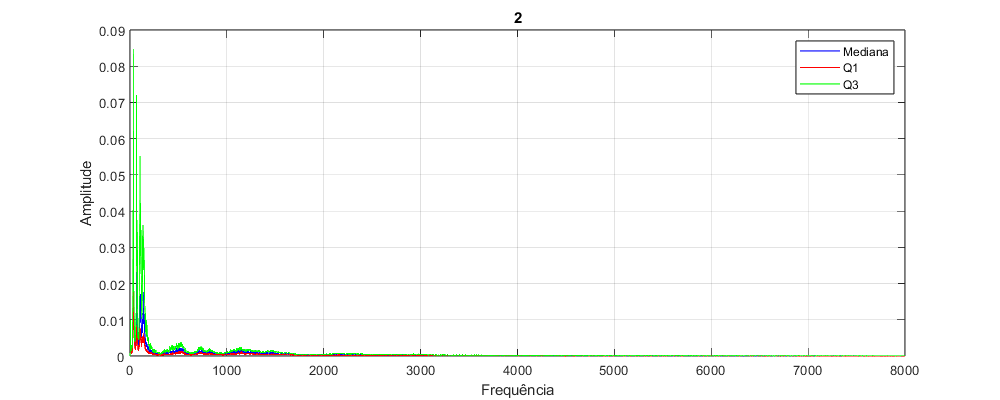

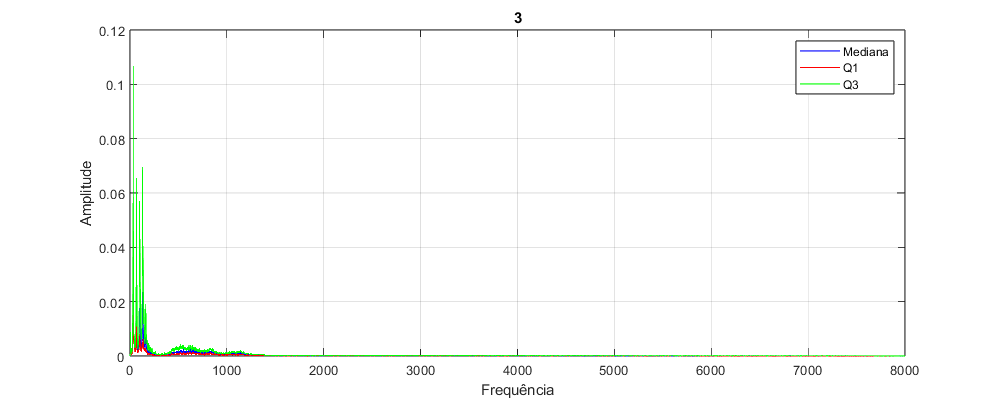

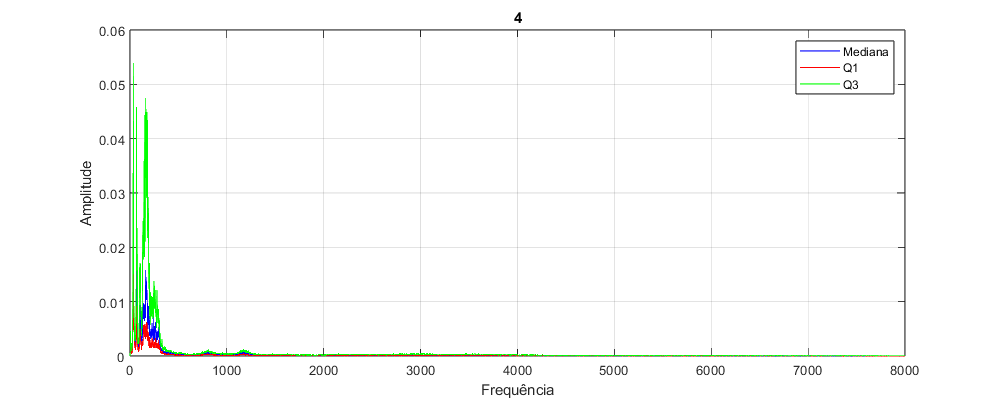

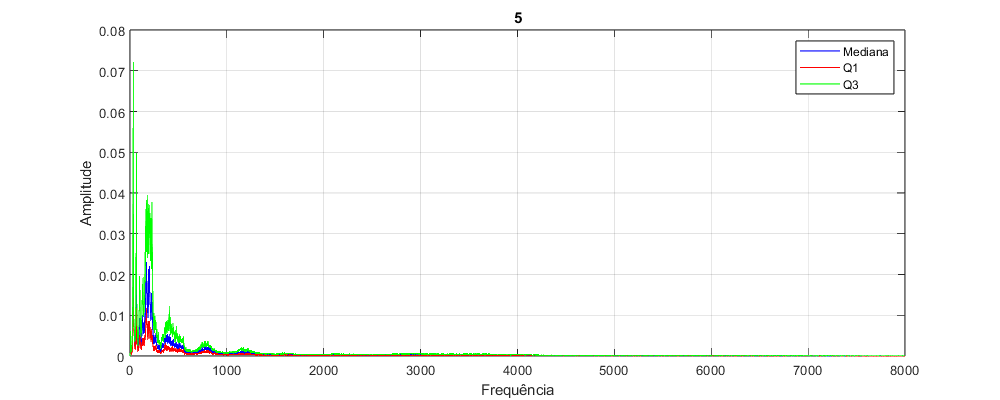

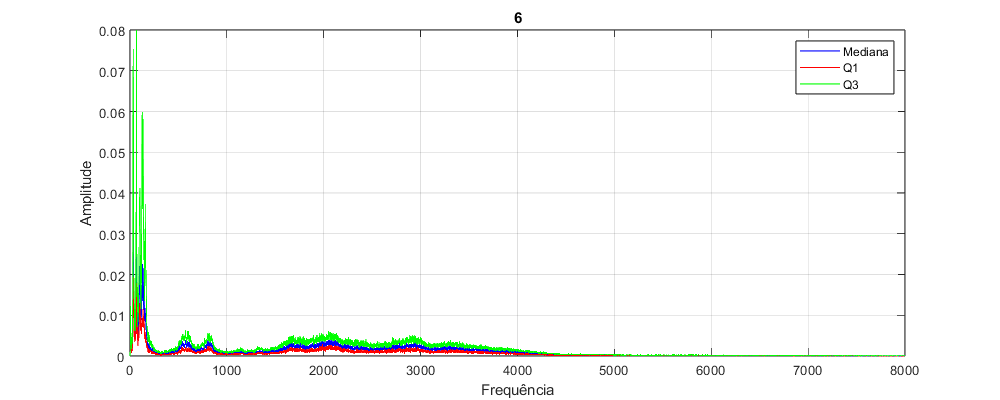

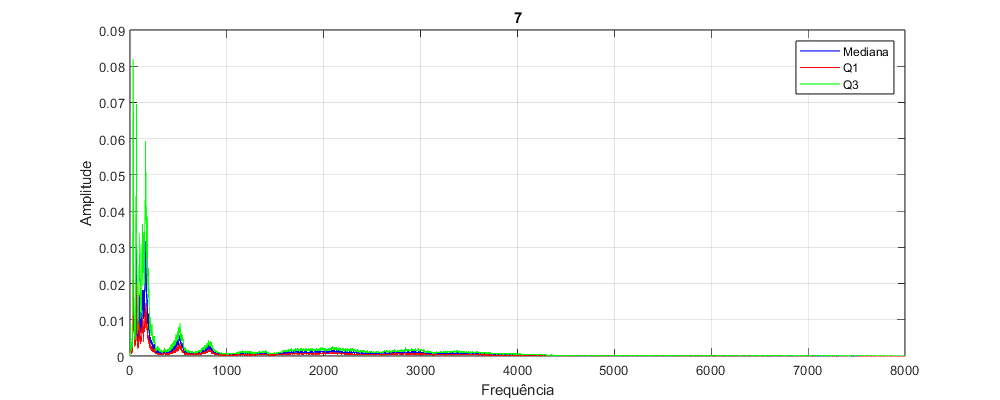

valorEixoFrequencia=8000;

for digito = 0:9
    indices = find([dados.digito] == digito);

    for i = indices
        coeficientesFourier = dados(i).coeficientesFourier;

        % Extrair apenas as frequências positivas (0 Hz até TaxaAmostragem/2)
        amplitudeFrequencias = abs(coeficientesFourier(1:length(coeficientesFourier)/2));

        espectro = [espectro; amplitudeFrequencias(:)'];
    end

    % Cálculo das estatísticas (Mediana, 1º quartil, 3º quartil)
    mediana = median(espectro, 1);
    q1 = quantile(espectro, 0.25, 1);
    q3 = quantile(espectro, 0.75, 1);

    % Criar vetor de frequências (todas as amostras têm o mesmo vetor)
    frequencias = linspace(0, valorEixoFrequencia, length(mediana));

    % Plotar espectro do dígito
    figure('Position', [100, 100, 1000, 400]);
    plot(frequencias, mediana, 'b'); hold on;
    plot(frequencias, q1, 'r');
    plot(frequencias, q3, 'g');
    title(digito);
    xlabel('Frequência');
    ylabel('Amplitude');
    legend('Mediana', 'Q1', 'Q3');
    grid on;
    xlim([0, valorEixoFrequencia]);
end

13. Identifique e implemente o cálculo de possíveis características espectrais que permitam a diferenciação entre dígitos como: máximos espectrais (posição e amplitude), médias espectrais, spectral edge frequency, etc. Deverá efetuar o cálculo para cada áudio de pelo menos 5 características espectrais e atualizar a sua estrutura de dados.

for i = 1:length(dados)
    taxaAmostragem = dados(i).taxaAmostragem;
    coeficientesFourier = dados(i).coeficientesFourier;

    % Apenas parte positiva do espectro
    amplitudeFrequencias = abs(coeficientesFourier(1:length(coeficientesFourier)/2));
    
    % Criar vetor de frequências
    Fv = linspace(0, taxaAmostragem/2, length(amplitudeFrequencias));

    % Cálculo das características espectrais
    [maxAmplitude, maxIdx] = max(amplitudeFrequencias);
    maxFrequencia = Fv(maxIdx);
    mediaAmplitude = mean(amplitudeFrequencias);

    % Cálculo da frequência SEF (95% da energia total)
    IntSpectrum = cumtrapz(Fv, amplitudeFrequencias);
    SEF_threshold = 0.95 * IntSpectrum(end);
    SEF = interp1(IntSpectrum, Fv, SEF_threshold, 'linear');

    % Guardar características na estrutura
    dados(i).maxEspetraisAmplitudes = maxAmplitude;
    dados(i).maxEspetraisPosicao = maxFrequencia;
    dados(i).mediaAmplitudesFrequencias = mediaAmplitude;
    dados(i).SEF = SEF;
    end

% Converter estrutura para tabela para visualização
tabela = struct2table(dados);
disp(tabela);

          diretorio            nomeFicheiro      participante    digito    repeticao         sinal          taxaAmostragem    taxaCruzamentoZeros    energiaTotal    tAmplitudeMaxima    razaoAmplitude    desvioPadrao    coeficientesFourier    maxEspetraisAmplitudes    maxEspetraisPosicao    mediaAmplitudesFrequencias     SEF  
    ______________________    _______________    ____________    ______    _________    ________________    ______________    ___________________    ____________    ________________    ______________

14. Recorrendo à representação gráfica das características espectrais extraídas no ponto anterior, identifique as três características que permitem uma melhor discriminação dos dígitos. Para isto pode utilizar boxplots, gráficos 2D, 3D, etc. Indique as características escolhidas.

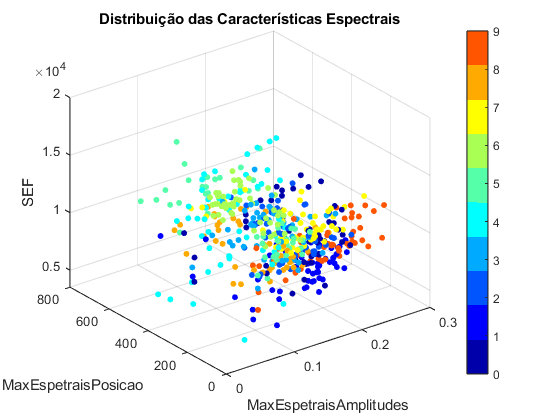

% Inicializar as caracteristicas a cruzar...
sinais = [dados.sinal];
valores1 = [dados.maxEspetraisAmplitudes];
valores2 = [dados.maxEspetraisPosicao];
valores3 = [dados.SEF];
digitos = [dados.digito];

figure;
scatter3(valores1, valores2, valores3, 20, digitos, 'filled');  
xlabel('MaxEspetraisAmplitudes');
ylabel('MaxEspetraisPosicao');
zlabel('SEF');
grid on;
title('Distribuição das Características Espectrais');

colormap(jet(10));  
caxis([0 9]); 
cor = colorbar;
cor.Ticks = 0:9;  
cor.TickLabels = {'0','1','2','3','4','5','6','7','8','9'};

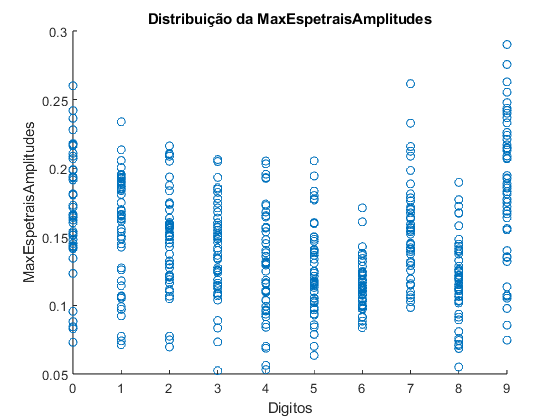

scatter(digitos,valores1,'o');
xlabel('Digitos');
ylabel('MaxEspetraisAmplitudes');
title('Distribuição da MaxEspetraisAmplitudes');

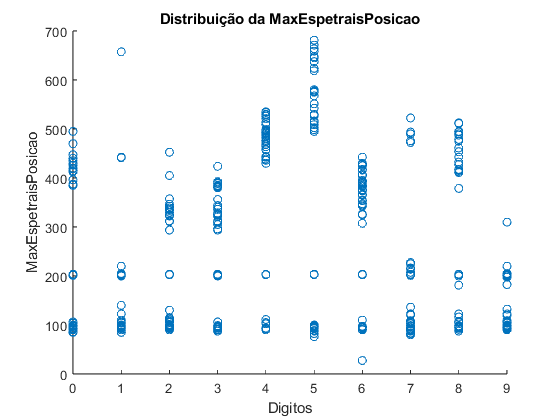

scatter(digitos,valores2,'o');
xlabel('Digitos');
ylabel('MaxEspetraisPosicao');
title('Distribuição da MaxEspetraisPosicao');

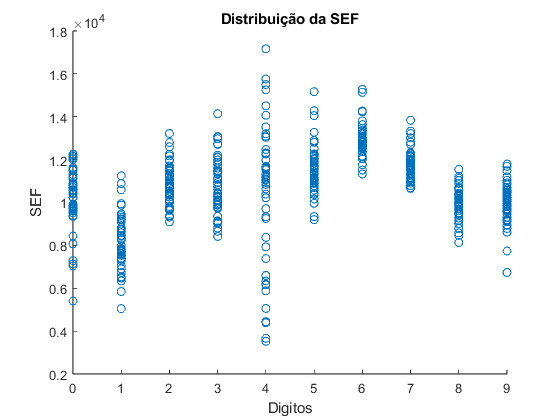

scatter(digitos,valores3,'o');
xlabel('Digitos');
ylabel('SEF');
title('Distribuição da SEF');

15. Atualize o ficheiro “.mat” carregado no início da meta com a estrutura de dados atualizada.

save('dados.mat',"dados")